# Обработка данных с помощью Live Tasks

Ускорение обработки данных с помощью "живых" задач (доступно с R2019b)

## Загрузка данных

Настраиваем хранилище данных, в виде папки с текстовыми файлами одинаковой структуры

ds = datastore('data');
ds.FileEncoding = 'Windows1251';
ds.DatetimeLocale = 'ru_RU';
preview(ds)

ans = 8×5 table
             time              ch1    ch2    ch3     ch4
    _______________________    ___    ___    ____    ___

    15.08.2017 19:37:26.759    -14    -16    -290     27
    15.08.2017 19:37:27.009      4     45     NaN     15
    15.08.2017 19:37:27.259      5    -12      53      5
    15.08.2017 19:37:27.509      5     12    -279     16
    15.08.2017 19:37:27.759     16      9      68    -11
    15.08.2017 19:37:28.009     15    -22     101     37
    15.08.2017 19:37:28.259     16     -4    -300      8
    15.08.2017 19:37:28.509      5    -12      17      8


Считываем данные из хранилища

data = readall(ds);

Переводим данные в формат t`imetable`

data = table2timetable(data);

Визуализируем данные таблицы

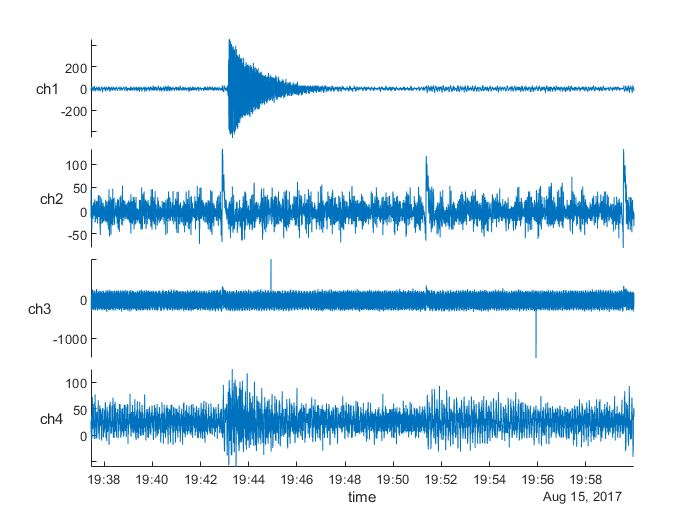

stackedplot(data);

## Обработка сигнала ch3

Обработаем сигнал `ch3` из таблицы `data` с помощью "живых" задач

### Замена выбросов

На графике сигнала c`h3` отчетливо видно несколько выбросов. Заполним их интерполированными значениями

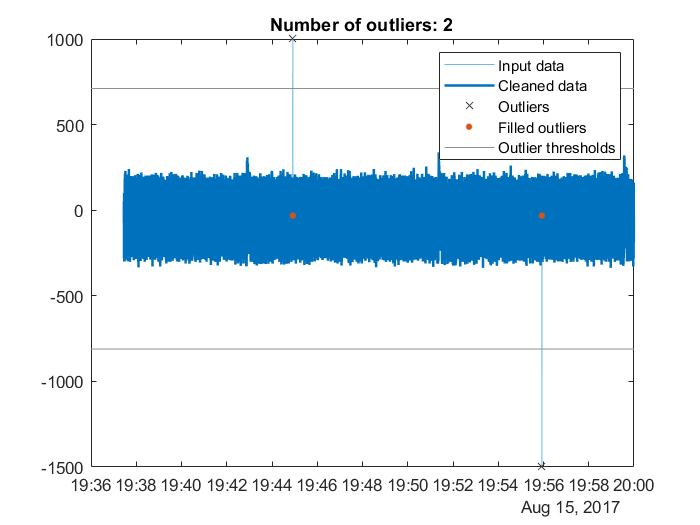

% Fill outliers
[ch31,outlierIndices,thresholdLow,thresholdHigh] = ...
    filloutliers(data.ch3,'linear','SamplePoints',data.time);

% Visualize results
clf
plot(data.time,data.ch3,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(data.time,ch31,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')

% Plot outliers
plot(data.time(outlierIndices),data.ch3(outlierIndices),'x',...
    'Color',[64 64 64]/255,'DisplayName','Outliers')
title(['Number of outliers: ' num2str(nnz(outlierIndices))])

% Plot filled outliers
plot(data.time(outlierIndices),ch31(outlierIndices),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','Filled outliers')

% Plot outlier thresholds
plot([xlim missing xlim],[thresholdLow*[1 1] NaN thresholdHigh*[1 1]],...
    'Color',[145 145 145]/255,'DisplayName','Outlier thresholds')

hold off
legend

clear outlierIndices thresholdLow thresholdHigh

### Замена пропусков

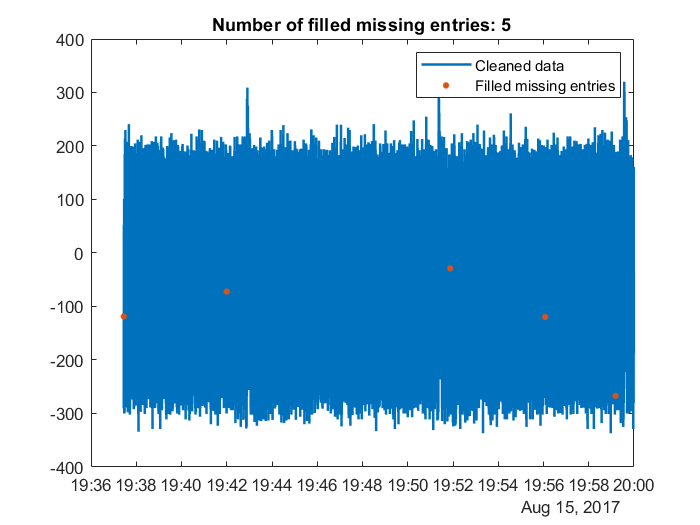

% Fill missing data
[ch32,missingIndices] = fillmissing(ch31,'linear',...
    'SamplePoints',data.time);

% Visualize results
clf
plot(data.time,ch32,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')
hold on

% Plot filled missing entries
plot(data.time(missingIndices),ch32(missingIndices),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','Filled missing entries')
title(['Number of filled missing entries: ' num2str(nnz(missingIndices))])

hold off
legend

clear missingIndices

### Осреднение шумов

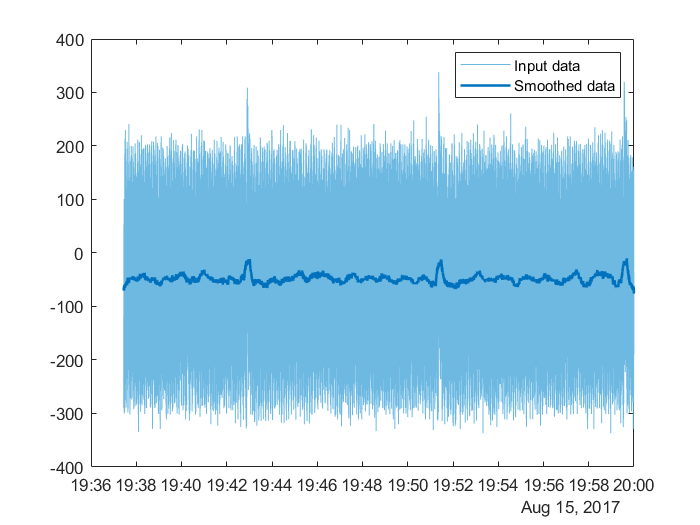

% Smooth input data
ch33 = smoothdata(ch32,'movmean',seconds(15),'SamplePoints',data.time);

% Visualize results
clf
plot(data.time,ch32,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(data.time,ch33,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend

## Передискретизация данных

Записываем обработанный сигнал ch3 в таблицу

data.ch3 = ch33;

Передискретизируем сигналы с тактом 0,25 с

data1 = retime(data, 'regular', 'linear', 'TimeStep', seconds(0.25));

Визуализируем данные

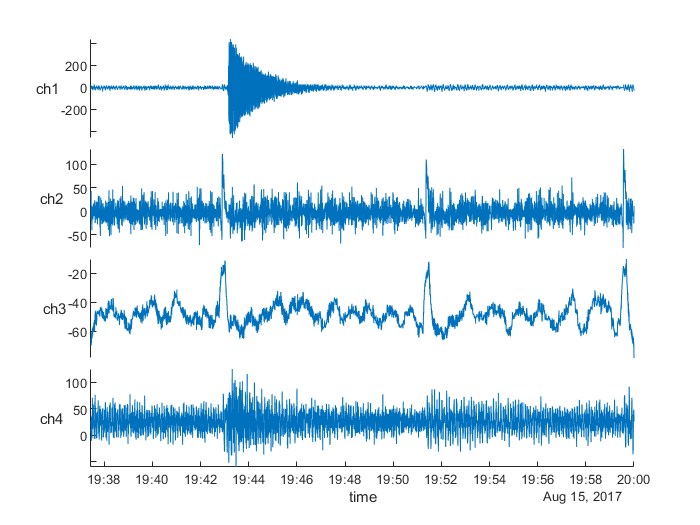

stackedplot(data1);

## Анализ сигналов

(*Signal Processing Toolbox*)

Переведем вектор времени в формат `duration` (длительность)

data2 = data1;
data2.time = data2.time - data2.time(1);

Запустим инструмент *Signal Analyzer*

signalAnalyzer(data2)

[Pavel Roslovets](http://roslovets.github.io)*, *[*ETMC Exponenta*](https://exponenta.ru/)* © 2019*